# SAR Test

## 실험 가정 및 파라미터 설계

탑재체의 출발부분부터 신호를 보낸다고 가정.

clear all;

c = 3*10^8;                             % 송수신속도 [m/s]
chirptau = 5;                           % 펄스 폭 [μs]
% tau = 10; [ns]

%--------------------------------------------------------------------------

h = 20000;                              % 탑재체 고도 [m]
gamma_m = 10;                           % 관측각도 [ °]

% < L-band > frequency : 1~2[GHz], wavelength : 15~30[cm]
% < X-band > frequency : 7.5~12[GHz], wavelength : 2.5~4[cm]
fc = 9;                                 % 운용주파수 [GHz]
lambda = c/(fc*10^9)                    % 파장 [m]

lambda = 0.0333

GmM/(h+Re)^2 = mv^2/h+Re (중력 = 원심력)

 v = sqrt(GM/(h+Re)) [중력상수 * 지구의 질량/ 탑재체로부터 지구중심까지의 거리]

G = 6.67*10^-11;                        % 중력상수
M = 5.98*10^24;                         % 지구의 질량 [kg]
Re = 6378000;                           % 지구반지름 [m]
v = sqrt(G*M/(h+Re))                    % 탑재체 속도 [m/s]

v = 7.8957e+03

 v_ground : 2*pi*Re = v : 2*pi*(h+Re) [지표에 비춰지는 빔의 속도, 탑재체 고도에 따라 변화]

v_ground = 2*pi*Re/(2*pi*(h+Re))*v;     % 지표에서의 빔 속도 [m/s]

L = 5;                                  % 안테나 길이 [m], 방위(azimuth)에 영향
W = 5;                                  % 안테나 폭 [m], 고도(elevation)에 영향
Ae = L*W*0.01;                          % 안테나 유효면적 [m^2]
eta = 70;                               % 안테나 효율 [%]

theta_az = 0.5*(lambda/L)*10^2;         % 안테나 빔 폭(azimuth) [ °]
theta_el = 0.5*(lambda/W)*10^2;         % 안테나 빔 폭(elevation) [ °]
A = 4*pi*Ae*(eta*10^-2)/lambda^2;       % 안테나 이득
A_dB = 10*log10(A);                     % 안테나 이득 [dB]  

Bandwidth = 150                         % 대역폭 [MHz]

Bandwidth = 150

delta_az = L/2                          % 방위 분해능 [m]

delta_az = 2.5000

delta_r = c/(2*Bandwidth*10^6)          % 거리 분해능 [m]

delta_r = 1


PRFmin = (2*v*sin(deg2rad(theta_az))... % 최소 PRF [Hz], PRFmax는 고려x
    *fc*10^9)/c

PRFmin = 2.7561e+03

PRImin = 1/PRFmin*10^6                  % 최소 PRI [μs], PRImax는 고려x

PRImin = 362.8304

NESZ (noise equivalent to sigma zero) 관측 대상에 따라 시스템 민감도 설정

KOMPSAT-5 기준 지표관측 : -17dB (0dB : 사람, -20dB : 새, -50dB : 벌레)

NESZ = -17;                             % 시스템 민감도 [dB]
Pt = 200;                               % 최대송신전력 [W]
duty = PRFmin*chirptau*10^-6*10^2       % 운용효율 [%]

duty = 1.3781

Pavg = Pt*duty*10^-2                    % 평균송신전력 [W]

Pavg = 2.7561

Gt = A_dB                               % 안테나 이득 [dB]

Gt = 32.9649

R = h/cos(deg2rad(gamma_m))             % 지표까지의 거리[m]

R = 2.0309e+04

k = 1.38*10^-23;                        % 볼츠만 상수
Te = 300;                               % 시스템 잡음 온도 [K]
NF =  3;                                % 시스템 잡음 [dB]
Ls = 10;                                % 시스템 손실 [dB]


SNR (signal to noise ratio)

SNR = (Pavg*Gt^2*(eta*0.01)^2*delta_r*NESZ^2)...
    /(8*pi^2*R^3*lambda*k*Te*NF*Ls*v)

SNR = 1.9619e+07

## +z축에서 바라본 탑재체 동선 및 송수신 신호간격

총 이동거리 300m

x = 0 : PRFmin*10^3 : 300/sqrt(2);      % x축
y = 0 : PRFmin*10^3 : 300/sqrt(2);      % y축
D = 0 : PRFmin*10^3 : 300;              
length(D)                               % 총 이동거리 [m]

ans = 1

t = length(D)/v                         % 총 이동시간 [s]

t = 1.2665e-04

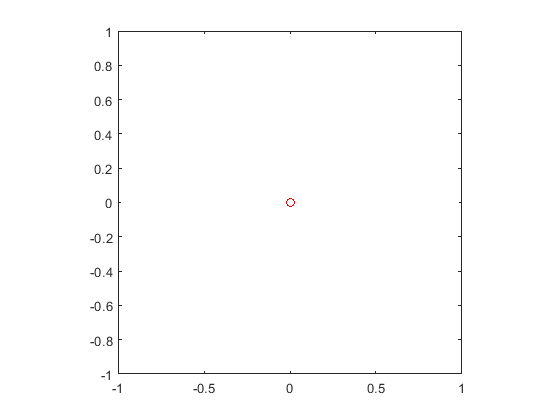

인덱스가 배열 요소 개수(1)를 초과합니다.

                               
plot(x,y)
axis('square');

hold on;
for i = 1:300 %length(D)      
    x_trans = 0 : PRFmin*10^3 : 300; %length(D)-1;
    y_trans = 0 : PRFmin*10^3 : 300; %length(D)-1;
    %pause(0.5);
    drawnow;
    plot(x_trans(i),y_trans(i),"Marker",'o',"Color",'r')
end

hold off;